# USB Webcam

This is a simple color object tracking USB camera tutoria for your robots.

Available USB webcam functions:

- webcamlist - List of webcams connected to your system

- webcam - Connection to a webcam

- preview - Preview live video dta from webcam

- snapshot - Acquire single image frame from a webcam

- closePreview - Close webcam preview window

Simrun Mutha and Jackie Zeng

clc % clear command window
clear % clear MATLAB workspace
% imagreset % clear all iamge objects

**Set up robot control system **

% Identifying available webcams: The webcamlist function provides a cell
% array of all webcams on the current system that MATLAB can acces. 
camList = webcamlist

camList = 2×1 cell array
    {'Integrated Webcam'            }
    {'Microsoft® LifeCam Cinema(TM)'}



% Connect to the webcam.
robotCam = webcam(2)

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
               Brightness: 143
                     Zoom: 0
               Saturation: 83
                      Pan: 0
                     Tilt: 0
                 Exposure: -6
         WhiteBalanceMode: 'auto'
             WhiteBalance: 4500
                FocusMode: 'auto'
             ExposureMode: 'auto'
                 Contrast: 5
    BacklightCompensation: 0
                    Focus: 3
                Sharpness: 25



% Fix auto exposure problem set it to manual, set exposure to work in lab
% lighting. Set whitebalance to manual too. Auto exposure and white balance
% drive computer vision algorithm crazy

SETUPUSBCAMERA(robotCam);

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
               Brightness: 143
                     Zoom: 0
               Saturation: 83
                      Pan: 0
                     Tilt: 0
                 Exposure: -6
         WhiteBalanceMode: 'auto'
             WhiteBalance: 4500
                FocusMode: 'auto'
             ExposureMode: 'manual'
                 Contrast: 5
    BacklightCompensation: 0
                    Focus: 3
                Sharpness: 25



% Preview Video Stream
preview(robotCam)
%wave hand in front to make sure its working
gCamTest = input('move hand in front of camera, type G and then hit Enter','s');
clc;

% close Preview Window
closePreview(robotCam);

% Acquire a frame
img = snapshot(robotCam);

% Display the frame in the imaqtool window
imtool(img);

%explore image with tool
gCamTest = input('experiment with tool, type G, then hit ENTER ','s');

clc;

%create a free floating figure for images
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow) % got to camWindow for imshow
imshow(img,'Border','tight')

% Save file
% filename = input('Input color of object:','s');
% saveas(gcf, filename)

% Identifying available webcams: The webcamlist function provides a cell
% array of all webcams on the current system that MATLAB can acces. 
camList = webcamlist

camList = 2×1 cell array
    {'Integrated Webcam'            }
    {'Microsoft® LifeCam Cinema(TM)'}



% Connect to the webcam.
robotCam = webcam(2)

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
               Brightness: 100
                     Zoom: 0
               Saturation: 83
                      Pan: 0
                     Tilt: 0
                 Exposure: -7
         WhiteBalanceMode: 'manual'
             WhiteBalance: 4500
                FocusMode: 'auto'
             ExposureMode: 'manual'
                 Contrast: 5
    BacklightCompensation: 0
                    Focus: 1
                Sharpness: 25



% Fix auto exposure problem set it to manual, set exposure to work in lab
% lighting. Set whitebalance to manual too. Auto exposure and white balance
% drive computer vision algorithm crazy

SETUPUSBCAMERA(robotCam);

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
               Brightness: 100
                     Zoom: 0
               Saturation: 83
                      Pan: 0
                     Tilt: 0
                 Exposure: -7
         WhiteBalanceMode: 'manual'
             WhiteBalance: 4500
                FocusMode: 'auto'
             ExposureMode: 'manual'
                 Contrast: 5
    BacklightCompensation: 0
                    Focus: 1
                Sharpness: 25


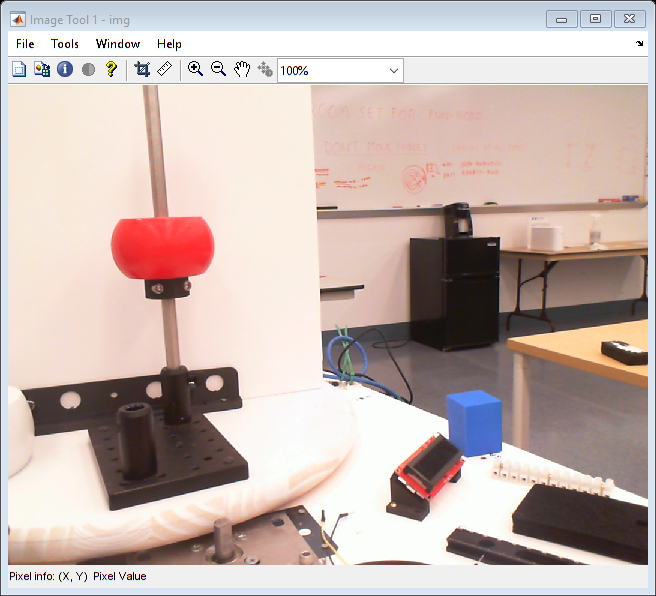

img = snapshot(robotCam);
imtool(img);

% filename = input('Input color of object:','s');
% saveas(gcf, filename)

nTests = 1

nTests = 1

r = rateControl(0.1);
reset(r);

**Run Robot Control Loop **


controlFlag = 1;

while (controlFlag < nTests +1)
    
    %SENSE finds centroid and area of target
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    [centroids, targetArea] = SENSE(robotCam, camWindow)
    THINK();
    ACT();
    
    %pause to allow you to move objects
    camtest = input('move objects to new position, type G, then hit ENTER', 's');
    clc;
    
    waitfor(r);                         % wait for loop cycle to complete
    controlFlag = controlFlag +1;       % increment loop
end


**Mission Data Processing**

% maybe save images

**Clean Shut Down**

% Stop program and clean up connection to WebCam when no longer needed

    clc
    clear robotCam
    disp('SimpleUSBCameraTutorial Done');
    
    beep

**General Functions**

function [] =  SETUPUSBCAMERA(robotCam)
    %SETUPUSBCAMERA creates and configures a Webcam to be a simple robot
    %vision system. It requires a standard Webcam attached to your computer
    %and takes webcam object name as sole input. You need to set your
    %cameras unique parameters to optimize picture 
    
    % Fix auto expose set it to manual, set whitebalance to manual too
    robotCam.ExposureMode = 'manual' %for LifeCam
    robotCam.WhiteBalanceMode = "manual";
    % experimentally determining best exposure setting for lab, enter here
    robotCam.Exposure = -7;
    robotCam.Brightness = 100;
    robotCam.Zoom = 0;
end

**Sense Functions**

function [centroids, targetArea] = SENSE(robotCam, camWindow)
    % This function acquires a single image from the USBCamera testCam and
    % finds and returns centroids of purple area in image
    
    % capture image
        robotImage = snapshot(robotCam);
    
    % use color threshold app to create a colormask funciton ( purplemaks)
    % functions will have different names depending on color of traget
        [targetMask, yellowImg] = yellowMask(robotImage);
        figure(camWindow)
        imshow(targetMask)
        camtest = input('check out masked image,type G, hit Enter','s');
        clc;

    % Preprocess image to remove noise
        se = strel('disk',50);
        cleanImage = imopen(targetMask, se) %structure element erosion function
        figure(camWindow)
        imshow(cleanImage)
        camtest = input('check out cleaned image, type G, then hit enter',"s")
        clc;

    % Calculate the centroid of the white part of masked area(target)
        targetCenter = regionprops(cleanImage,'centroid');
    % Store the x and y coordinates in a two column matrix
        centroids = cat(1,targetCenter.Centroid);
    % Display the original image with the centroid locations superimposed
        figure(camWindow) % go to camWindow for imshow
        imshow(robotImage)
        hold on
        plot(centroids(:,1),centroids(:,2),'b*')
        text(centroids(:,1),centroids(:,2), 'Target Centroid')
        hold off
        camtest = input('check out target center, type G, and hit enter','s');
        clc;

    % Calculate the area of the target
        targetArea = regionprops(cleanImage,'area');
        area = targetArea.Area;
    % Store the x and y coordinates in a two column matrix
        centroids = cat(1,targetCenter.Centroid);
    % Display the binary image with the centroid locations superimposed
        figure(camWindow) % go to camWindow for imshow
        imshow(robotImage)
        hold on
        plot(centroids(:,1),centroids(:,2),'b*')
        plot(centroids(:,1),(centroids(:,2) + 10),num2str(area));
        hold off
        camtest = input('check out target center, type G, and hit enter','s');
        clc
end